# The TranClass class

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

The `TranClass` is a class to support 2-D transformation for astronomical images. 

This file is accessible through the `manual` package (i.e. `manual.mextractor`). Specifically, it can be used to represent an arbitrary 2-D transformation, to fit, apply and manipulate this transformation. TranClass contains some static methods and some methods.

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

## Transformation representation

Transformations in TranClass are represented as linear combinations of supported functions. Each functional can be multiplied by a coeficient called the function parameter.

Currently, the following functions are available:

- FunOne - A shift function.

- FunX     - Function linear in X.

- FunY     - Function linear in Y.

- FunXY   - Function linear in X.*Y.

- FunTiltXp - Tip tilt function in X of the form: X.*(X+Y)

- FunTiltYp - Tip tilt function in Y of the form: Y.*(X+Y)

- FunTiltXn - Tip tilt function in X of the form: X.*(X-Y)

- FunTiltYn - Tip tilt function in Y of the form: Y.*(X-Y)

- FunPolyXY - General polynomials in X and Y.

- FunPolyChebyshev1XY - General Chebyshev polynomials of the first kind in X and Y.

- FunPolyChebyshev2XY - General Chebyshev polynomials of the second kind in X and Y.

## Properties

`TranClass` has the folliowing properties:

Fun - This property contains for each dimension, the set of functions. This is a cell array of cell arrays. The first cell represents the dimension index while the second cell is for the functions. For example: {{`@FunOne`, `@FunX`},{`@FunOne`, `@FunX`, `@FunY`, `@FunTiltXp`}} represent the 2-D transformation:

X' = a_1 + a_2*X

Y' = b_1 + b_2*X + b_3*Y + b_4*X*(X+Y)

FunArg - Some functions requires arguments like the function order. This is a cell array of cell arrays that contains the functions arguments.

NPar - A cell array that contains the number of free parameters per function.

Par - Cell array of the parameters that multiply the functions (e.g., a_1, a_2).

ParErr - Cell array of the parameter errors.

# Methods and examples

## **Constructor**

Use the method constructor `TranClass` to create a transformation:

TranC=TranClass({@FunOne,[],@FunPolyXY,[1 2;2 3]}, {@FunOne,[],@FunPolyXY,[1 3; 1 1]});
TranC

TranC =   TranClass with properties:

       Fun: {{1×2 cell}  {1×2 cell}}
    FunArg: {{1×2 cell}  {1×2 cell}}
      NPar: {{1×2 cell}  {1×2 cell}}
       Par: []
    ParErr: []


TranC(1).Fun{1}

ans =     @FunOne    @FunPolyXY


TranC(1).FunArg{1}{2}

ans =      1     2
     2     3


TranC(1).NPar{1}

ans =     [1]    [2]


In this example the transformation is:

X' = a_1 + a_2*X*Y^2 + a_3*X^2*Y^3

Y' = b_1 + b_2*X*Y + b_3*X^3*Y

## Constructing useful transformations

Constructing affine transformation:

TranC =  TranClass({@FunOne, [],@FunX,[],@FunY,[]}, {@FunOne, [],@FunX,[],@FunY,[]});

Constructing affine + tip tilt transformation:

TranC =  TranClass({@FunOne, [],@FunX,[],@FunY,[],@FunTiltXp,[],@FunTiltXn,[]}, {@FunOne, [],@FunX,[],@FunY,[],@FunTiltYp,[],@FunTiltYn,[] });

TranC =   TranClass with properties:

       Fun: {{1×4 cell}  {1×3 cell}}
    FunArg: {{1×4 cell}  {1×3 cell}}
      NPar: {{1×4 cell}  {1×3 cell}}
       Par: []
    ParErr: []


Construcing affine + 2nd deg Chebyshev:

ParDeg = [1 1;2 0;0 2;2 1;1 2];
TranC =  TranClass({@FunOne, [],@FunX,[],@FunY,[],@FunPolyChebyshev1XY,ParDeg}, {@FunOne, [],@FunX,[],@FunY,[],@FunPolyChebyshev1XY,ParDeg});

H =     [10×5 double]    [10×3 double]


## **Single function Evaulation**

You can use the static method TranClass.evalfun to evaulate a single functional at some parameters:

[Out,NPar]=TranClass.evalfun(@FunOne,[],'X',[1;1]);

ans =             1      0.77684      0.76905       0.4641      0.27726
            1      0.47551      0.07164     0.016198    0.0005518
            1      0.33042     0.097079     0.010599   0.00033996
            1      0.17336      0.15627    0.0046963   0.00012722
            1       0.0349      0.78754   0.00095925   2.6365e-05
            1      0.77291      0.51668      0.30866      0.12326
            1      0.63681     0.054953     0.022285   0.00077986
            1      0.31331      0.43718     0.042916    0.0058783
            1      0.43935      0.32646     0.063016    0.0090384
            1      0.52219       0.7534      0.20544     0.080823


or

% [Out,NPar]=TranClass.evalfun(@MyNewFun,[],'X',[1;1],'Y',[2;3],'Mag',[1;2]);

## **The design matrix**

In order to evaluate or fit a full set of function we need to construct the design matrix.

The following example, define some transformation in X and Y, define some random coordinates and calculate the design matrix for X and Y.

TranC = TranClass({@FunOne, [],@FunX,[],@FunY,[],@FunPolyXY,[2 3;1 2]}, {@FunOne, [],@FunX,[],@FunY,[]})
X=rand(10,1); Y=rand(10,1);
H=design_matrix(TranC,'X',X,'Y',Y)

  Set gain to 1
mextractor first pass - Constructing optimal PSF
  Set gain to 1
  No filter found - Use DefFilter
  Estimate images background and std


  Subtract background
  Filter image number 1 - use 1 filters
    Threshold image and locate local maxima
    Extracting 4349 sources
  Calculate 1st and 2nd moments


  Filter image number 2 - use 1 filters
    Threshold image and locate local maxima
    Extracting 4249 sources
  Calculate 1st and 2nd moments


mextractor second pass - Source detection and measurments
  Subtract background


  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 7430 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)
  Filter image number 2 - use 2 filters
    Threshold image and locate local maxima
    Extracting 7184 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)


H{1}

Using the design matrix we can fit or evaluate the transformation.

## **Fit transformation**

The method fit_transform can be used to fit transformation to data sets. The function has many options and full help is available via the help or doc commands. Here we show some simple examples:

% Read 2 FITS images into a SIM object
S=FITS.read2sim('test_PTF_*f02_p004162_c08.fits');
% extract sources
S=mextractor(S);
% match sources in the two images by coordinates

TranC =   TranClass with properties:

       Fun: {{1×5 cell}  {1×5 cell}}
    FunArg: {{1×5 cell}  {1×5 cell}}
      NPar: {{1×5 cell}  {1×5 cell}}
       Par: []
    ParErr: []


[AstM]=match(S);
% prepare an array of matched sources
[MatchedCat]=astcat2matched_array(AstM,{'XWIN_IMAGE','YWIN_IMAGE','MAG_PSF'});

ans =              TranC: [1×1 TranClass]
               Dim: [1×2 struct]
             Resid: [7430×1 double]
              Flag: [7430×1 logical]
          wmed_rms: 0.042015
               rms: 0.19227
              rrms: 0.17826
            rmsAll: 0.31399
    AssymptoticRMS: 0.028812


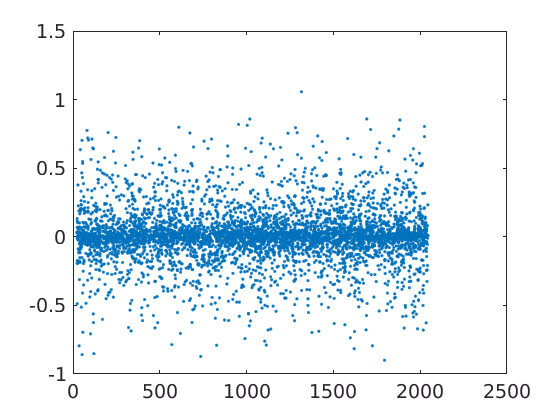

% define the transformation to fit
TranC = TranClass({@FunOne, [],@FunX,[],@FunY,[],@FunTiltXp,[],@FunTiltXn,[]}, {@FunOne, [],@FunX,[],@FunY,[],@FunTiltYp,[],@FunTiltYn,[] })
% Fit the transformation to the list of matched sources

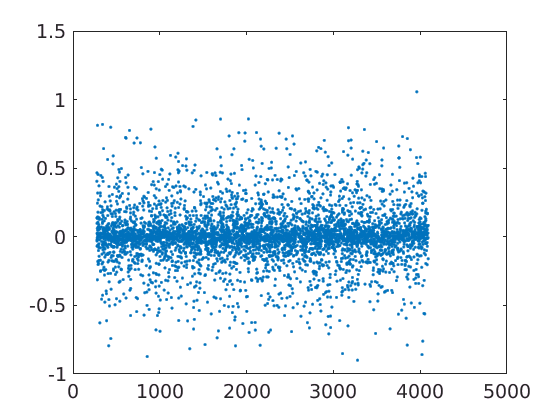

Res=fit_transform(TranC,MatchedCat);
Res(2)

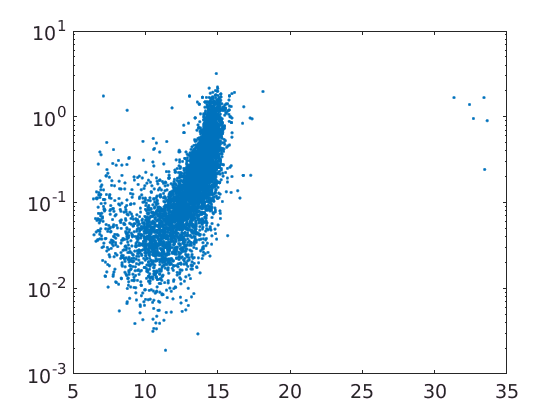

%plot residuals:
%X vs ResX

plot(Res(2).Dim(1).Coo(Res(2).Flag), Res(2).Dim(1).Resid(Res(2).Flag),'.')
%Y vs. ResX

eran     21137  0.0  0.0 227524 126104 pts/39  S    Jan15   0:31 ds9
ds9 is already open


plot(Res(2).Dim(2).Coo(Res(2).Flag), Res(2).Dim(1).Resid(Res(2).Flag),'.')
% The rms vs. magnitude
semilogy(MatchedCat.MAG_PSF(:,2),Res(2).Resid,'.')
%mark stars that were used for the best fit transformation
ds9(S(2)); ds9.plot([Res(2).Dim(1).Coo( Res(2).Flag ), Res(2).Dim(2).Coo( Res(2).Flag )]);

In this example Res(1) contain the transformation between the reference image and itself, while Res(2) contains the information regarding the transformation between the fisr and second images.

## **Apply the transformation**

After the transformation is found one can apply ito images or catalogs. For example the `SIM` methods `SIM/transform `and `SIM/align` can be used to apply a transformation to SIM images.

The following example use the align function that uses the fit_transform and SIM/transform function to register images:

% Read two FITS images into a SIM object
S=FITS.read2sim('test_PTF_*f02_p004162_c08.fits');
% Extract the sources
S=mextractor(S);
% Define the transformation to use
% Note that this is the default transformation so in practice this is not needed
TranC = TranClass({@FunOne, [],@FunX,[],@FunY,[],@FunTiltXp,[],@FunTiltXn,[]}, {@FunOne, [],@FunX,[],@FunY,[],@FunTiltYp,[],@FunTiltYn,[] });
% fit the transformation and register the images
[AlSim,ResFit,I]=align(S,'TranC',TranC);

## **Additional methods**

Som additional TranClass methods to manipulate the content of an object more easily are: `populate_par` and `par2vector`.

Two additional importnat functions are `tranclass2poly` and `tranclass2PolynomialTransformation2D` that can represent the TranClass object in the form of a general polynomials.